# Evaluate the Model

Instructions are in the task pane to the left. Complete and submit each task one at a time.

Do not edit. This code loads the data.

clear;clc
load letterfeatures.mat
testdata

testdata = 968×26 table
    AspectRatio     MADX       MADY        AvgU        MADU        AvgV       MADV      CorrXY      CorrXP       CorrXU       CorrXV       CorrYP       CorrYU        CorrYV       CorrPU      CorrPV       CorrUV     NumXMin    NumXMax    NumYMin    NumYMax    NumUMin    NumUMax    NumVMin    NumVMax    Character
    ___________    _______    _______    _________    _______    ________    ______    _______

knnmodel = fitcknn(traindata,"Character","NumNeighbors",5);
predictions = predict(knnmodel,testdata)

predictions = 968×1 categorical array
     E 
     A 
     G 
     J 
     M 
     P 
     T 
     Z 
     A 
     M 
     K 
     R 
     S 
     T 
     K 
     B 
     C 
     D 
     F 
     I 
     K 
     O 
     R 
     S 
     V 
     V 
     B 
     E 
     G 
     J 
     K 
     N 
     O 
     A 
     A 
     Y 
     A 
     C 
     E 
     L 
     O 
     A 
     R 
     R 
     V 
     A 
     P 
     C 
     D 
     G 
     F 
     N 
     O 
     P 
     S 
     M 
     K 
     V 
     W 
     Z 
     A 
     D 
     P 
     Z 
     A 
     G 
     J 
     K 
     M 
     O 
     P 
     A 
     W 
     G 
     D 
     I 
     Y 
     Z 
     Q 
     Z 
     A 
     B 
     M 
     P 
     V 
     P 
     F 
     Q 
     U 
     Y 
     Z 
     D 
     G 
     L 
     M 
     R 
     U 
     X 
     H 
     L 
     T 
     V 
     G 
     D 
     E 
     J 
     A 
     L 
     M 
     N 
     W 
     A 
     A 
     B 
     C 
     D 
     D 
     A 
     D 
     E 
  

How good is the kNN model? The table `testdata` includes the known class for the test observations. You can compare the known classes to the kNN model's predictions to see how well the model performs on new data.

## Task 1

Use the `==` operator to compare `predictions` to the known classes (stored in the variable `Character` in the table `testdata`). Store the result in a variable called `iscorrect`.

iscorrect = (predictions == testdata.Character)

iscorrect = 968×1 logical array
   1
   0
   1
   1
   1
   1
   1
   1
   0
   1


## Task 2

Calculate the proportion of correct predictions by dividing the number of correct predictions by the total number of predictions. Store the result in a variable called `accuracy`. You can use the `sum` function to determine the number of correct predictions and the `numel` function to determine the total number of predictions.

notcorrect = (predictions ~= testdata.Character)

notcorrect = 968×1 logical array
   0
   1
   0
   0
   0
   0
   0
   0
   1
   0


misclassrate = sum(notcorrect)/numel(predictions)

misclassrate = 0.2324

Rather than accuracy (the proportion of correct predictions), a commonly-used metric to evaluate a model is *misclassification rate* (the proportion of incorrect predictions).

## Task 3

Use the `~=` operator to determine the misclassification rate. Store the result in a variable called `misclassrate`.

accuracy = sum(iscorrect)/numel(predictions)

accuracy = 0.7676

Accuracy and misclassification rate give a single value for the overall performance of the model, but it can be useful to see a more detailed breakdown of which classes the model confuses. A *confusion matrix* shows the number of observations for each combination of true and predicted class.

A confusion matrix is commonly visualized by shading the elements according to their value. Often the diagonal elements (the correct classifications) are shaded in one color and the other elements (the incorrect classifications) in another color. You can visualize a confusion matrix by using the `confusionchart` function.

`confusionchart``(``ytrue``,``ypred``)``;`

where `ytrue` is a vector of the known classes and `ypred` is a vector of the predicted classes.

## Task 4

Use the `confusionchart` function to compare `predictions` to the known labels (stored in the variable `Character` in the table `testdata`).

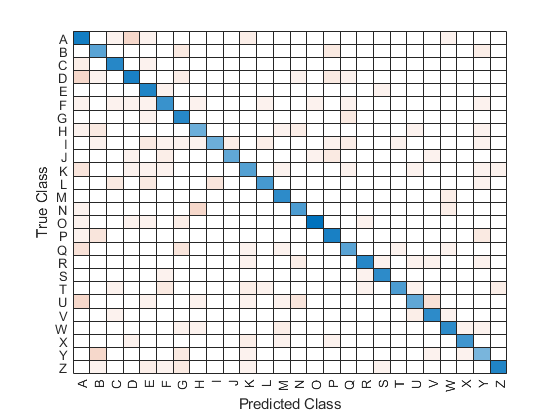

ans =   ConfusionMatrixChart with properties:

    NormalizedValues: [26×26 double]
         ClassLabels: [26×1 categorical]

  Show all properties


confusionchart(testdata.Character,predictions)

## Further Practice

It can be useful to investigate the features of commonly confused classes. Try using the logical array of incorrect classifications to index into `testdata` and `predictions` to obtain the data for the misclassified observations. Where do these observations live in the feature space? From this, can you tell why these observations were misclassified?